# Ajuste Reología

Ejercicio de ajuste de datos experimentales del vídeo aspectos básicos de Reología para la Goma Tara.

Inicio

clear
clc

Carga de datos

data=readtable("Reo1.csv")

data = 63×2 table
    Rate    Stress
    ____    ______

    0.01     0.93 
    0.02     1.86 
    0.03     1.86 
    0.04     2.33 
    0.05     2.33 
    0.06     2.33 
    0.07     2.33 
    0.08     2.33 
    0.09     2.33 
    0.19     2.79 
    0.28     3.72 
    0.37     4.65 
    0.47     5.12 
    0.56     6.51 
    0.65    16.74 
    0.74    13.95 


Repartición en variables

shearrate=data.Rate;
shearstress=data.Stress;

## Ajuste por el modelo de Herschel & Bulkley

Ecuación del modelo


$$\tau=k\dot{\gamma}^m+\tau_0$$


hereschelbulkley=@(b,x)b(1)*x.^b(2)+b(3);

Parámetros iniciales

initialparameters=[1 1 0];

Subrutina de ajuste

[fittedStress,b,R2]=reological_adjustment(shearrate,shearstress,hereschelbulkley,initialparameters);

Grado de ajuste

fprintf('R-squared value: %.4f\n', R2);

R-squared value: 0.9934


Parámetros del modelo

k=b(1)

k = 5.2008

m=b(2)

m = 0.5767

tau0=b(3)

tau0 = 2.2543

Grafica

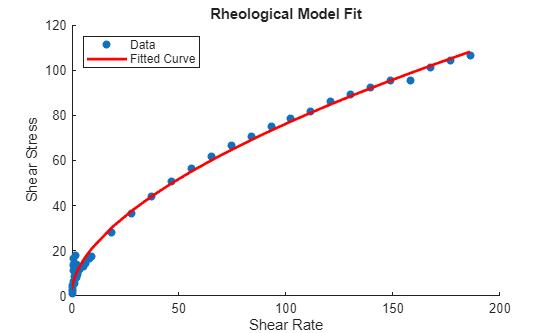

% Plot the original data and the fitted curve
figure;
scatter(shearrate, shearstress, 'filled');
hold on;
plot(shearrate, fittedStress, 'r-', 'LineWidth', 2);
xlabel('Shear Rate');
ylabel('Shear Stress');
title('Rheological Model Fit');
legend('Data', 'Fitted Curve','Location','northwest');
hold off;

## Ajuste por método de Cross

Viscosidad aparente


$$\eta=\frac{\tau}{\dot{\gamma}}$$


eta=shearstress./shearrate;

Modelo de Cross


$$\eta=\frac{\eta_0}{1+\alpha\dot{\gamma}^n}$$


modelocross=@(bb,x)bb(1)./(1+bb(2)*x.^bb(3));

Ajuste

initialCrossParams = [1, 1, 1]; % Initial guess for parameters
[fittedEta,bb,R2]=reological_adjustment(shearrate,eta,modelocross,initialCrossParams);

Grado de Ajuste

fprintf('Cross model R-squared value: %.4f\n', R2);

Cross model R-squared value: 0.9549


Gráfica

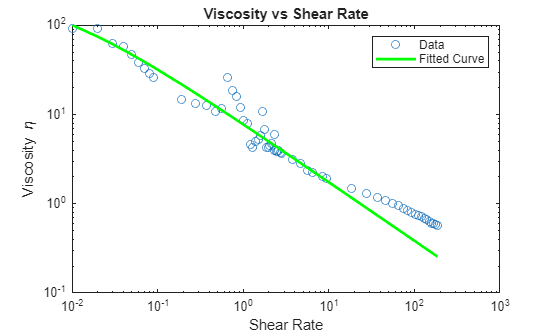

loglog(shearrate,eta,'o')
title('Viscosity vs Shear Rate');
xlabel('Shear Rate');
ylabel('Viscosity \eta');
hold on;
% Plot the fitted viscosity curve
loglog(shearrate, fittedEta, 'g-', 'LineWidth', 2);
legend('Data', 'Fitted Curve');
hold off;